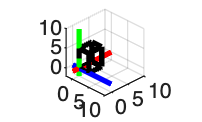

%pintar ejes
line ([-2 10], [0 0], [0 0], 'Color','blue','LineWidth',2)
line ([0 0], [-2 10], [0 0], 'Color','red','LineWidth',2)
line ([0 0], [0 0], [-2 10], 'Color','green', 'LineWidth',2)
hold on
grid on
view(45, 30);
axis equal

%pedir dimensiones
ancho = input(" Introduce el ancho: ");
largo = input(" Introduce el largo: ");
alto = input(" Introduce el alto: ");
theta = input(" Introduce el angulo de rotacion sobre el eje Z: ");

%puntos de la base (z = 0)
x1a = 0;    y1a = 0;
x2a = ancho;   y2a = 0;
x3a = ancho;   y3a = largo;
x4a = 0;    y4a = largo;

%base inferior
line([x1a x2a], [y1a y2a], [0 0], 'Color','black', 'LineWidth',2)
line([x2a x3a], [y2a y3a], [0 0], 'Color','black','Linewidth', 2)
line([x3a x4a], [y3a y4a], [0 0], 'Color','black', 'linewidth', 2)
line([x4a x1a], [y4a y1a], [0 0], 'Color','black', 'LineWidth',2)

%paredes verticales
line ([x1a x1a], [y1a y1a], [0 alto], 'Color','black','LineWidth',2)
line ([x2a x2a], [y2a y2a], [0 alto], 'Color','black','LineWidth',2)
line ([x3a x3a], [y3a y3a], [0 alto], 'Color','black','LineWidth',2)
line ([x4a, x4a], [y4a, y4a], [0 alto], 'Color','black','LineWidth',2)

%tapa superior (z = alto)
line ([x1a x2a], [y1a y2a], [alto alto], 'Color','black','LineWidth',2)
line ([x2a x3a], [y2a y3a], [alto alto], 'Color','black','LineWidth',2)
line ([x3a x4a], [y3a y4a], [alto alto], 'Color','black','LineWidth',2)
line ([x4a x1a], [y4a y1a], [alto alto], 'Color','black','LineWidth',2)

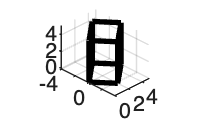



for i = 0:0.1:theta
clf
  x1 = x1a*cos(i) - y1a*sin(i);
  y1 = x1a*sin(i) + y1a*cos(i);

  x2 = x2a*cos(i) - y2a*sin(i);
  y2 = x2a*sin(i) + y2a*cos(i);

  x3 = x3a*cos(i) - y3a*sin(i);
  y3 = x3a*sin(i) + y3a*cos(i);

  x4 = x4a*cos(i) - y4a*sin(i);
  y4 = x4a*sin(i) + y4a*cos(i);

%base inferior
line([x1 x2], [y1 y2], [0 0], 'Color','black', 'LineWidth',2)
line([x2 x3], [y2 y3], [0 0], 'Color','black','Linewidth', 2)
line([x3 x4], [y3 y4], [0 0], 'Color','black', 'linewidth', 2)
line([x4 x1], [y4 y1], [0 0], 'Color','black', 'LineWidth',2)

%paredes verticales
line ([x1 x1], [y1 y1], [0 alto], 'Color','black','LineWidth',2)
line ([x2 x2], [y2 y2], [0 alto], 'Color','black','LineWidth',2)
line ([x3 x3], [y3 y3], [0 alto], 'Color','black','LineWidth',2)
line ([x4, x4], [y4, y4], [0 alto], 'Color','black','LineWidth',2)

%tapa superior (z = alto)
line ([x1 x2], [y1 y2], [alto alto], 'Color','black','LineWidth',2)
line ([x2 x3], [y2 y3], [alto alto], 'Color','black','LineWidth',2)
line ([x3 x4], [y3 y4], [alto alto], 'Color','black','LineWidth',2)
line ([x4 x1], [y4 y1], [alto alto], 'Color','black','LineWidth',2)


axis equal
    grid on
    view(45,30)

    drawnow

pause (0.2)


end 